Stress-strain data for carbon steel

% Strain [mm/mm]
strain_exp = [0, 500/210000, 0.003749347, 0.005234888, ...
    0.007631515, 0.011446096, 0.017384888, ...
    0.026405375, 0.039775799];
% Stress [MPa]
stress_exp = [0, 500, 550, 600, 660, 720, 780, 840, 900];

Ramberg-Osgood Equation

Fit of the experimental data.

E = s
K = 1480;    % MPa
n = 6.71;
stress_fit = linspace(0, stress_exp(end), 100);
strain_fit = stress_fit/E + (stress_fit/K).^n;


Plot

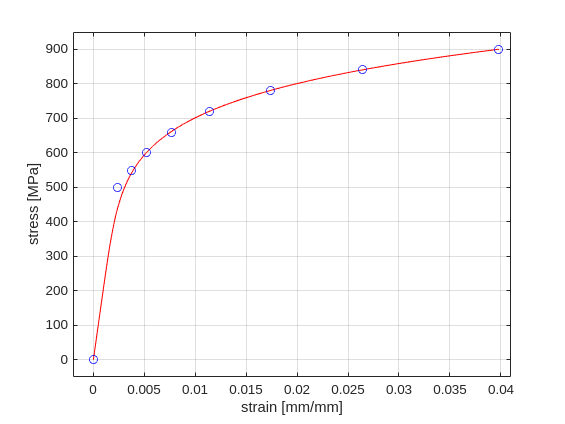

figure;
plot(strain_fit, stress_fit, 'r-');
hold on
plot(strain_exp, stress_exp, 'bo')
axis([-0.002, 0.041, -50, 950])
xlabel('strain [mm/mm]');
ylabel('stress [MPa]')
legend('Ramberg-Osgood fit', 'Measured data')
grid('on')

References:

- [https://www.quadco.engineering/en/know-how/fea-ramberg-osgood-equation.htm](https://www.quadco.engineering/en/know-how/fea-ramberg-osgood-equation.htm)